# Task 1: MATLAB Image Analysis

The purpose of this project is to get familiar with the image analysis and statistics functions in the image processing toolbox in MATLAB.  Review the following functions before working on this project:

This project will implement identification of different sized gears and washers in the “GearsAndWashers.tif” image using blob analysis in MATLAB.  Print all intermediate images.

**Report:**

- Write your code in the MATLAB Live Scripts using the template provided.

- Comment your code sufficiently.

- Save the live scripts code with its output in a PDF file.

## a)  Blob detection and boundary plotting  

In the GearsAndWashers.tif image:

- Put a boundary on each of the object and a number label identifying them.  

- Print the properties (mean intensity, area, perimeter, centroid, diameter) of each of the object.

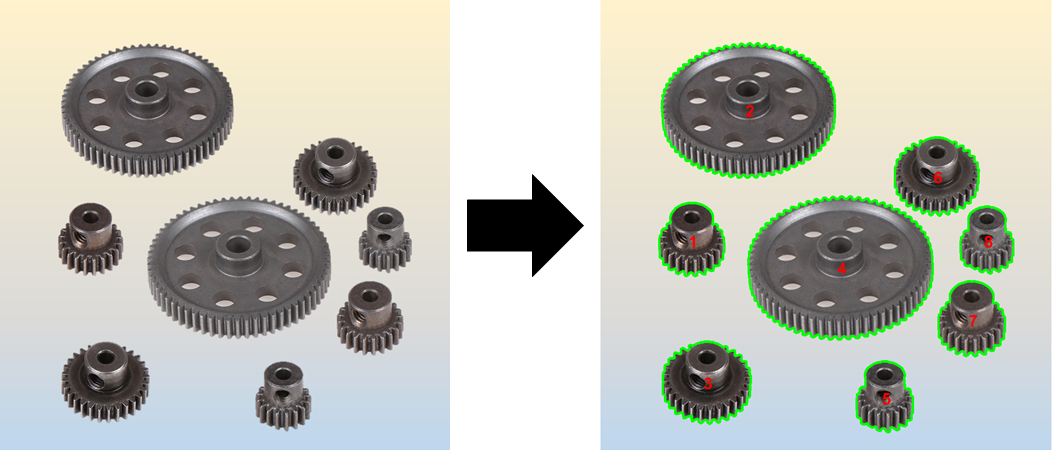

i.  Convert the image to a clean binary image with no holes by thresholding and `imfill` function.

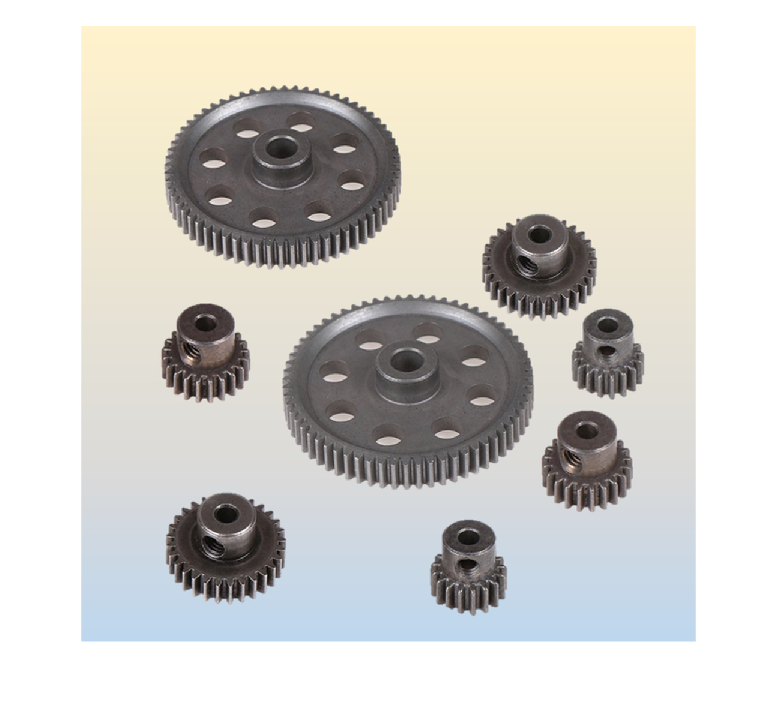

% Read and show the original image.

orig_gears = imread("Gears.tif");
imshow(orig_gears)

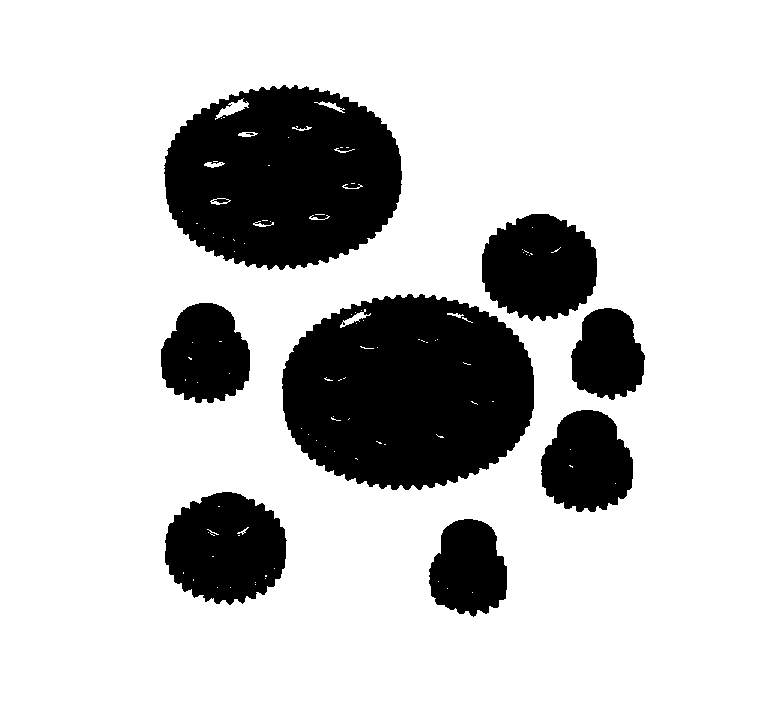

% Use a threshold value to convert from grayscale to a binary image and 
% show the resulting image.
threshold = 0.8;
grey_gears = im2bw(orig_gears, threshold);
imshow(grey_gears);

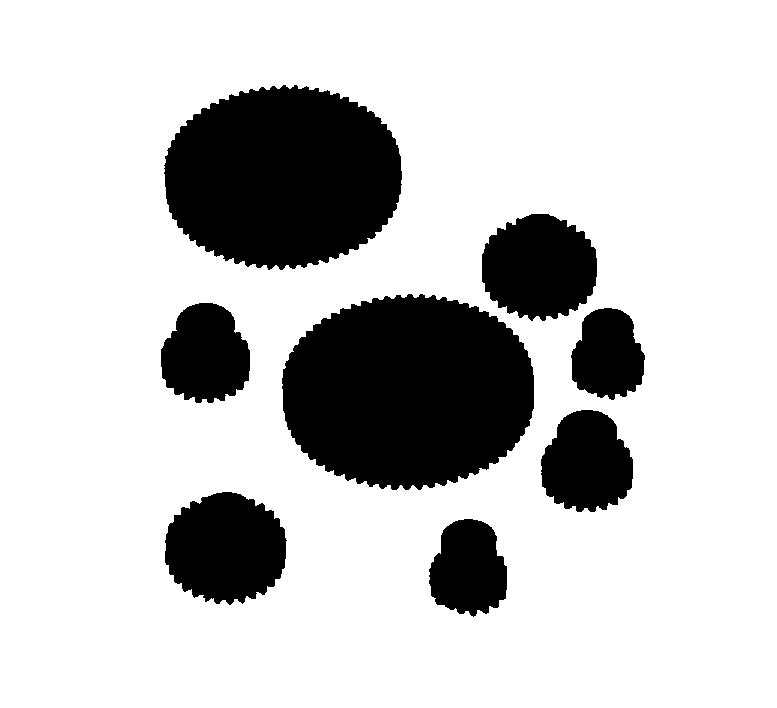

% Perform  a "hole fill" to get rid of holes in the gears and any background pixels 
% inside the blobs and show the resulting image.
%gear_flipped = imcomplement(grey_gears);
gear_filled = imfill(~grey_gears, 'holes');
%gear_filled = imcomplement(gear_filled_flipped);
imshow(~gear_filled)

ii.  Use the `bwlabel` command to generate a labeled image showing each of the blobs in the image.    

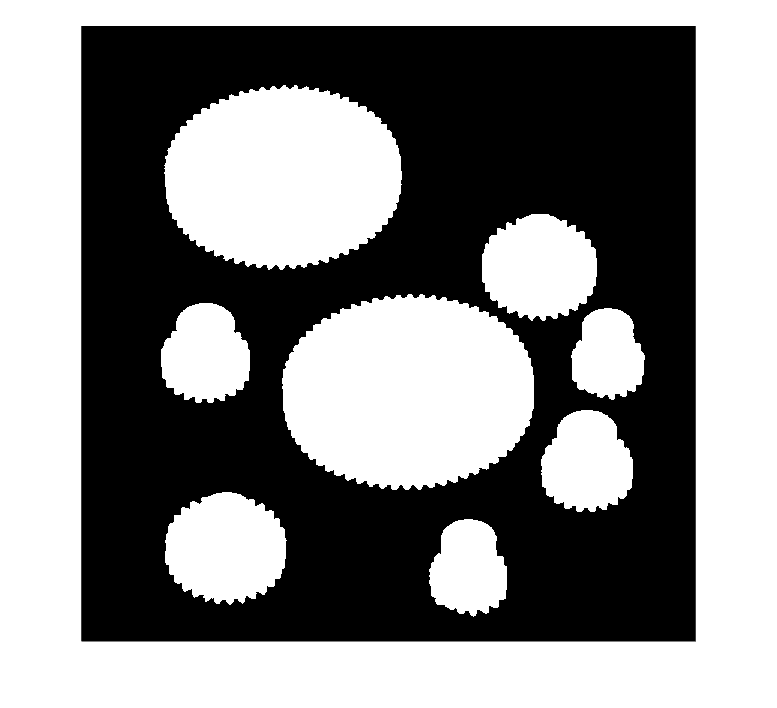

% Label blobs in the image and show the resulting image.
[labeledImage, numBlobs] = bwlabel(gear_filled);

imshow(labeledImage)

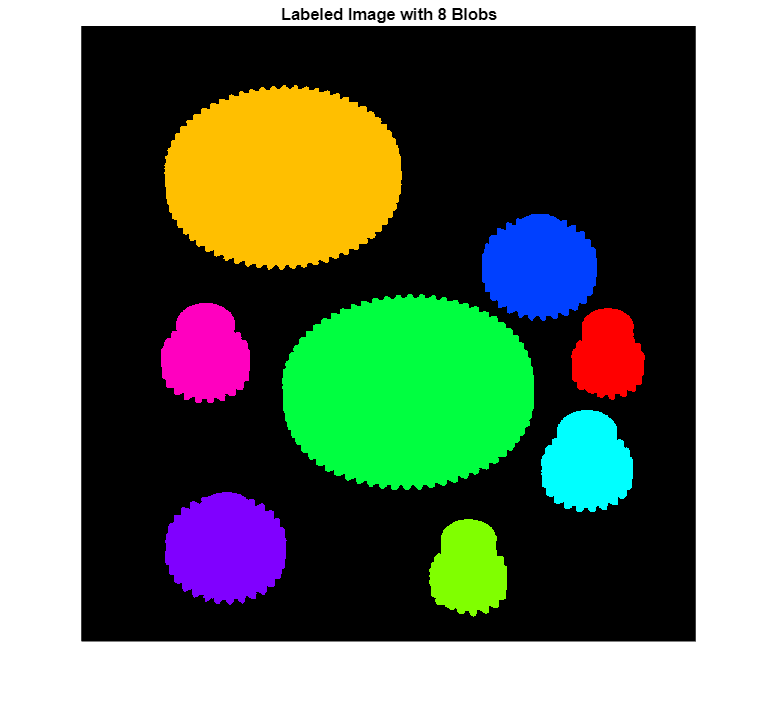

% Show labels in pseudo random colors.

colormap = rand(numBlobs, 3);
NumGears = label2rgb(labeledImage, 'hsv', 'k', 'shuffle');
imshow(NumGears)
title(['Labeled Image with ', num2str(numBlobs), ' Blobs']);

iii.  Use the `regionprops` command to get the number of blobs found and the properties of each of the blobs.

% Get the number and properties of blobs found.

blobregions = regionprops(labeledImage)

blobregions = 8×1 struct array with fields:
    Area
    Centroid
    BoundingBox


iv.  Use the `bwboundaries` command to plot the boundary of each of the blobs found on the original grayscale image to highlight the objects.

% bwboundaries returns a cell array where each cell contains the 
% row/column coordinates for an object in the image.

gearBoundries = bwboundaries(labeledImage)

gearBoundries = 8×1 cell array
    { 545×2 double}
    {1282×2 double}
    { 716×2 double}
    {1364×2 double}
    { 490×2 double}
    { 678×2 double}
    { 556×2 double}
    { 457×2 double}


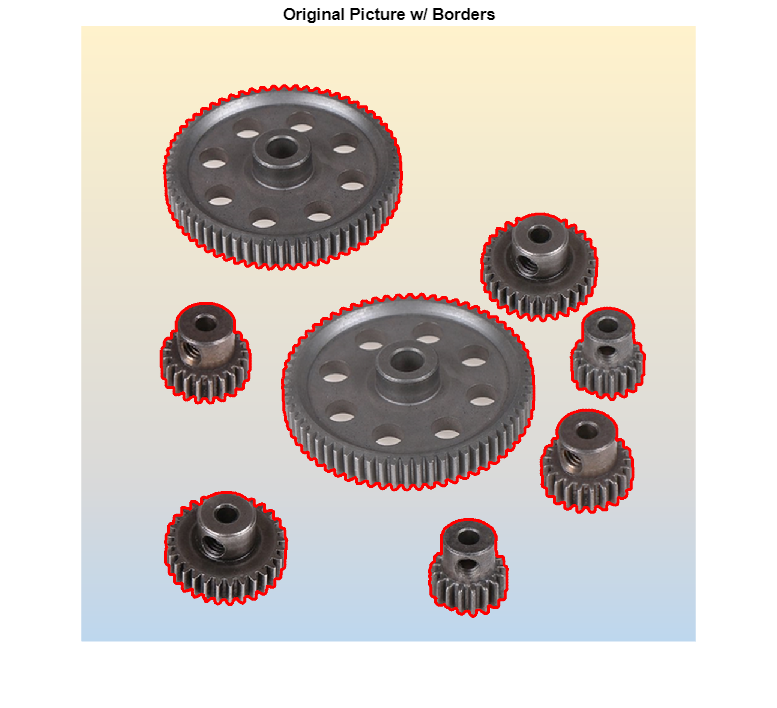

% Plot the borders of all the objects on the original grayscale image 
% using the coordinates returned by bwboundaries.

figure;
imshow(orig_gears);
title('Original Picture w/ Borders');

hold on;

for k = 1:length(gearBoundries)
    boundary = gearBoundries{k};
    plot(boundary(:, 2), boundary(:, 1), 'r', 'LineWidth', 2);
end

hold off;

v.  Print the blob properties (mean intensity, area, perimeter, centroid, diameter) of each blob found and plot blob number labels on the objects in the outlined grayscale image.


disp(propertyTable);

Unrecognized function or variable 'propertyTable'.

% Put the blob number labels on the boundaries grayscale image.



##    b)	  Find the different object types in the image

Identify the different object types (large gears, medium-large gears, medium-small gears, and small gears) in the image using the blob properties obtained in part (a) and extract them in separate images. 

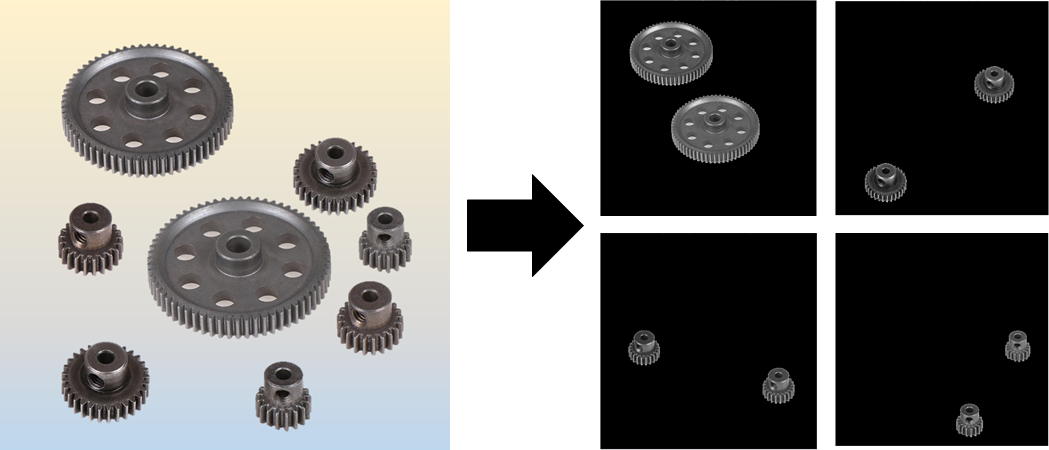

i.  Check blob properties from part (a) and identify which criteria to use to separate the four different types of the objects. 

% Check criteria of blob properties from part(a)(v) to select the best one to 
% separate object types



ii.  Use the `ismember` function to extract the selected blobs in the labeled image that was generated in part (a) using the `bwlabel` command.   Create a binary mask from the labeled image and filter each type of the object for display in the original grayscale image.

% Extract large gears by selecting the blobs in the labeled image that meet 
% the criteria and show the binary image mask with separated gears.



% Use the binary image mask to filter out the large gears from the grayscale image 
% and show the original image with only the separated gears.



% Extract medium-large gears by selecting the blobs in the labeled image that meet 
% the criteria and show the binary image mask with separated gears.



% Use the binary image mask to filter out the medium gears from the grayscale image 
% and show the original image with only the separated gears.



% Extract medium-small gears by selecting the blobs in the labeled image that meet 
% the criteria and show the binary image mask with separated gears.



% Use the binary image mask to filter out the medium-small gears from the grayscale image 
% and show the original image with only the separated gears.



% Extract small gears by selecting the blobs in the labeled image that meet 
% the criteria and show the binary image mask with separated gears.



% Use the binary image mask to filter out the small gears from the grayscale image 
% and show the original image with only the separated gears.



##   c)	  Find the brightest medium-large gear in the image

Identify the brightest medium-large gear in the image using the blob intensity and other properties obtained in part (a) and extract it in a separate image.

i.  Check blob properties from part (a) and identify which criteria to use to separate the brightest medium-large gear.

% Compare the area of the gears using the blob properties to separate
% medium-large gears and set up the criteria to find the brightest one.



ii.  Use the `ismember` function to extract the identified blobs in the labeled image that was generated in part (a) using the `bwlabel` command.  Create a binary mask from the labeled image and filter the brightest medium-large gear for display in the original grayscale image.

% Extract the brightest medium-large gear by selecting the blobs in the labeled image that 
% meet the criteria and show the binary image mask with separated gear.



% Use the binary image mask to filter out the brightest medium-large gear from the 
% grayscale image and show the original image with only that gear.

